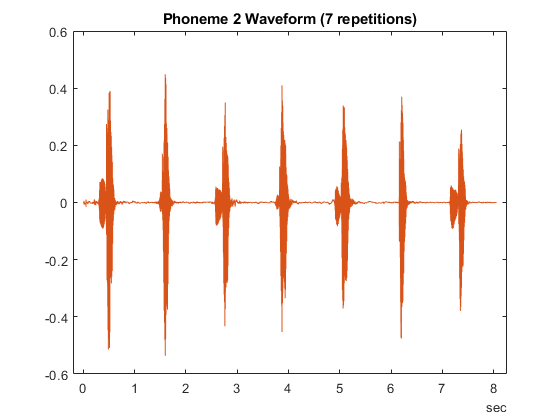

fileName ="Phonemes\2.mp3";
plotAudio(fileName);
title("Phoneme 2 Waveform (7 repetitions)");

%{

    Calibration:

    - This stage is there to mimic some form of calibration for a user,
    similar to how many voice assistants need a vocal sample to deal with.

    - This process takes multiple copies of the same word/phoneme and then
    creates an "average" of those waveforms, by doing this the level of
    variance the user can have on their voice when they are saying
    something to be speech recognized will be generally closer to the
    average.

%}

% Subsecting the Audio based on Peaks
[audioStereo, fs] = audioread(fileName);
audioMono = audioStereo(:,1);
[peaks, locs] = findpeaks(audioMono,fs);
max(abs(peaks))

ans = 0.4489